clear

# **SPRO3 - WS Interface**

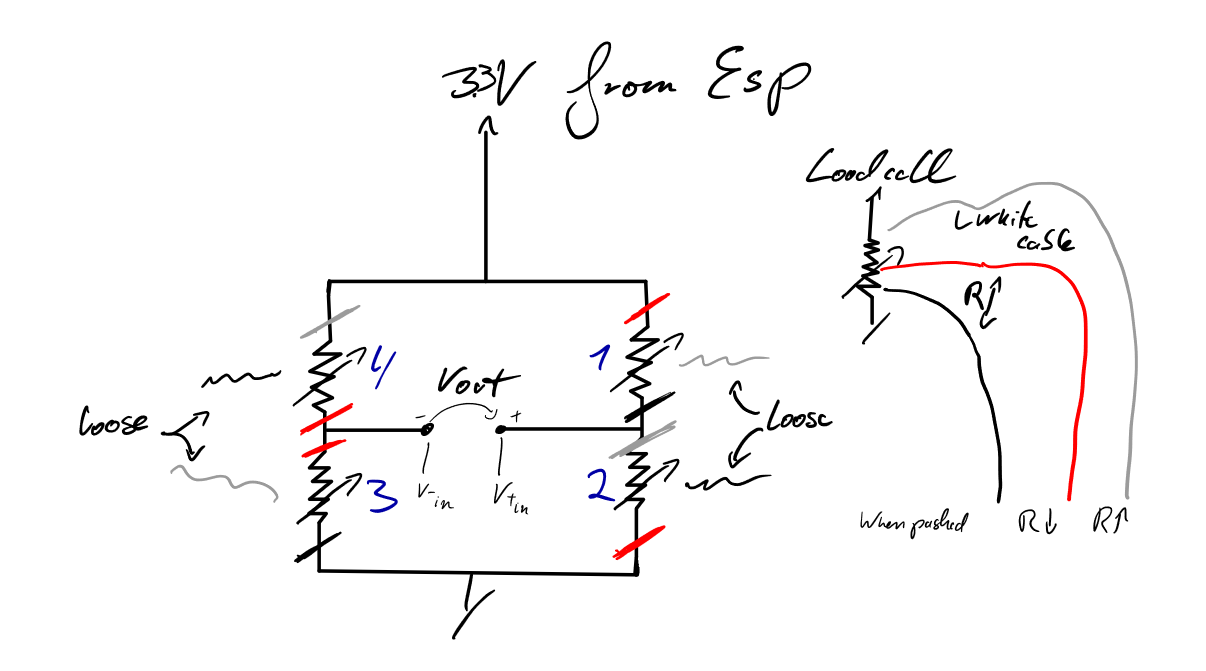

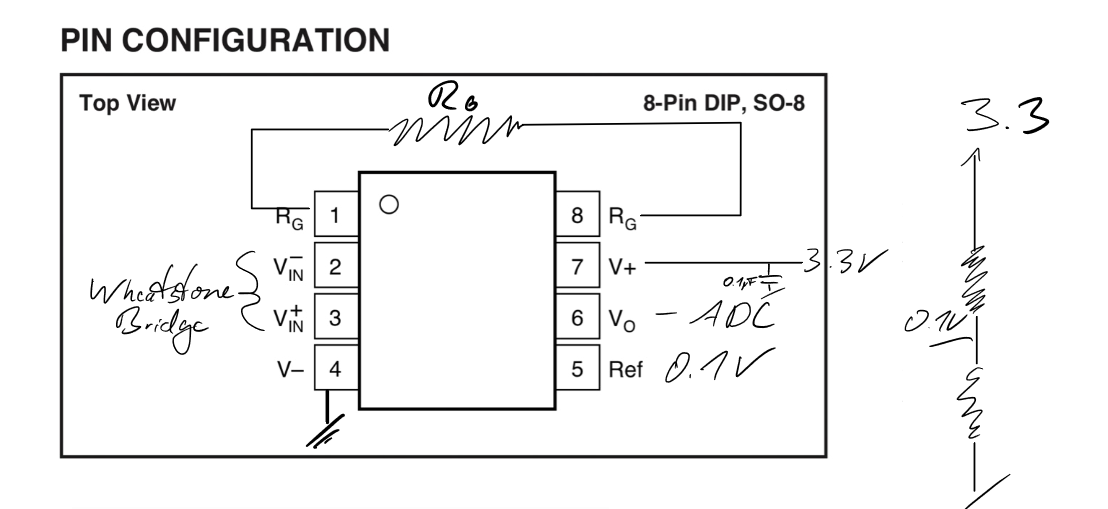

# Desired Range for the ADC

Vin_ADC_min = 0.2

Vin_ADC_min = 0.2000

Vin_ADC_max = 2.25

Vin_ADC_max = 2.2500


O_span = Vin_ADC_max - Vin_ADC_min

O_span = 2.0500

# Data Input from measurements

V_out_ESP = 3.3; % V
V_supply_wheatstone = V_out_ESP; % V

% Numbering of the loadcells is clockwise starting in the upper right
% corner - up is where the power supply goes in

% np: not pressed
% pd: pressed down
% Rwr: Resistance between white and red cable
% Rrb: Resistance between red and black cable

loadcell1 = struct('npRwr',996,'npRrb',996,'pdRwr',999,'pdRrb',995);
loadcell2 = struct('npRwr',997,'npRrb',997,'pdRwr',998,'pdRrb',996);
loadcell3 = struct('npRwr',996,'npRrb',997,'pdRwr',997,'pdRrb',997);
loadcell4 = struct('npRwr',997,'npRrb',996,'pdRwr',999,'pdRrb',994);


# Construction of Wheatstone Bridge

#### Scenario - No load

R1 = loadcell1.npRrb

R1 = 996

R2 = loadcell2.npRwr

R2 = 997

R3 = loadcell3.npRrb

R3 = 997

R4 = loadcell4.npRwr

R4 = 997


V_out_wheatstone_np = V_supply_wheatstone * (R2/(R1+R2)) - V_supply_wheatstone * (R3/(R3+R4))

V_out_wheatstone_np = 8.2790e-04

I_l12_np = V_supply_wheatstone / (R1 + R2)

I_l12_np = 0.0017

I_l34_np = V_supply_wheatstone / (R3 + R4)

I_l34_np = 0.0017

#### Scenario - Full load

R1 = loadcell1.pdRrb

R1 = 995

R2 = loadcell2.pdRwr

R2 = 998

R3 = loadcell3.pdRrb

R3 = 997

R4 = loadcell4.pdRwr

R4 = 999


V_out_wheatstone_pd = V_supply_wheatstone * (R2/(R1+R2)) - V_supply_wheatstone * (R3/(R3+R4))

V_out_wheatstone_pd = 0.0041

I_l12_pd = V_supply_wheatstone / (R1 + R2)

I_l12_pd = 0.0017

I_l34_pd = V_supply_wheatstone / (R3 + R4)

I_l34_pd = 0.0017


I_span = V_out_wheatstone_pd - V_out_wheatstone_np;

# Gain resistor and offset

desired_Gain = O_span / I_span

desired_Gain = 619.5034


syms R_G
required_R_G = vpasolve(desired_Gain == 5 + 200*10^3/R_G, R_G) 

$$required\_R\_G = 325.46603940747750347011450495571$$

%0 = -desired_Gain + 5 + 200*10^3/required_R_G
%required_R_G = ((desired_Gain - 5) / 200*10^3)^(-1)


% Voltage divider at Vref

LTSpice sim - not pressed   

    --- Operating Point ---

V(vs):	 3.3	 voltage

V(vin+):	 1.65083	 voltage

V(vin-):	 1.65001	 voltage

V(ref):	 0.145591	 voltage

V(n001):	 1.65091	 voltage

V(n003):	 1.65009	 voltage

V(vout):	 0.402276	 voltage

V(n002):	 1.99439	 voltage

I(R1):	 0.00165579	 device_current

I(R2):	 0.0016558	 device_current

I(R3):	 0.00165497	 device_current

I(R4):	 0.00165496	 device_current

I(R5):	 3.15441e-05	 device_current

I(R6):	 4.6589e-05	 device_current

I(Rg):	 1.26272e-06	 device_current

I(R8):	 -1.24864e-05	 device_current

I(R9):	 1.37392e-05	 device_current

I(R10):	 1.37724e-05	 device_current

I(R11):	 -1.50449e-05	 device_current

I(V1):	 -0.00377156	 device_current

Ix(u1:1):	 -1.18717e-08	 subckt_current

Ix(u1:2):	 -9.87161e-09	 subckt_current

Ix(u1:99):	 0.000205662	 subckt_current

Ix(u1:50):	 -0.000218126	 subckt_current

Ix(u1:45):	 1.2486e-05	 subckt_current

Ix(u2:1):	 -1.18717e-08	 subckt_current

Ix(u2:2):	 -9.87177e-09	 subckt_current

Ix(u2:99):	 0.000223619	 subckt_current

Ix(u2:50):	 -0.000196087	 subckt_current

Ix(u2:45):	 -2.75109e-05	 subckt_current

LTSpice sim - pressed

       --- Operating Point ---

V(vs):	 3.3	 voltage

V(vin+):	 1.65497	 voltage

V(vin-):	 1.64752	 voltage

V(ref):	 0.145518	 voltage

V(n001):	 1.65505	 voltage

V(n003):	 1.6476	 voltage

V(vout):	 2.45289	 voltage

V(n002):	 1.73911	 voltage

I(R1):	 0.00165496	 device_current

I(R2):	 0.00165497	 device_current

I(R3):	 0.00165414	 device_current

I(R4):	 0.00165413	 device_current

I(R5):	 3.15448e-05	 device_current

I(R6):	 4.65657e-05	 device_current

I(Rg):	 1.13507e-05	 device_current

I(R8):	 7.97841e-06	 device_current

I(R9):	 3.36244e-06	 device_current

I(R10):	 3.66028e-06	 device_current

I(R11):	 -1.50209e-05	 device_current

I(V1):	 -0.00376933	 device_current

Ix(u1:1):	 -1.18713e-08	 subckt_current

Ix(u1:2):	 -9.87132e-09	 subckt_current

Ix(u1:99):	 0.000214505	 subckt_current

Ix(u1:50):	 -0.000206505	 subckt_current

Ix(u1:45):	 -7.97841e-06	 subckt_current

Ix(u2:1):	 -1.18719e-08	 subckt_current

Ix(u2:2):	 -9.87193e-09	 subckt_current

Ix(u2:99):	 0.000214195	 subckt_current

Ix(u2:50):	 -0.000207151	 subckt_current

Ix(u2:45):	 -7.02272e-06	 subckt_current